% run startup
% run("car_startup.m");

clear all
close all
clc

% Pojazd Lancer 1.5, 955 kg
A = 2.18; % m^2
cx = 0.3;
f0 = 0.01;
eff = 0.9;
Pmax = 80; %kW
g=9.81;
m = 955; %kg
rd = 0.360; % m
brake_force=7500; %N
start_speed=0; %m/s

%Parametry silnika
Mmax = 147; %Nm
n_Mmax = 4500; %rpm

rpm_gear_up = 5000;
rpm_gear_down = 2500;

% Parametry skrzyni biegów
ibi = [3.31 1.91 1.31 0.97 0.81]; % przełożenia
starting_gear = 1; % bieg początkowy
ig=4.53; % przekładnia główna
gear_max=5;

% parametry wzniesienia
angle=0;

run("csv_import");
csv_data = data{:,:};
sz = size(csv_data);
csv_data(sz(1),:) = [];

torque_curve_f = polyfit(csv_data(:,1), csv_data(:,2), 2);


## Krzywa momentu

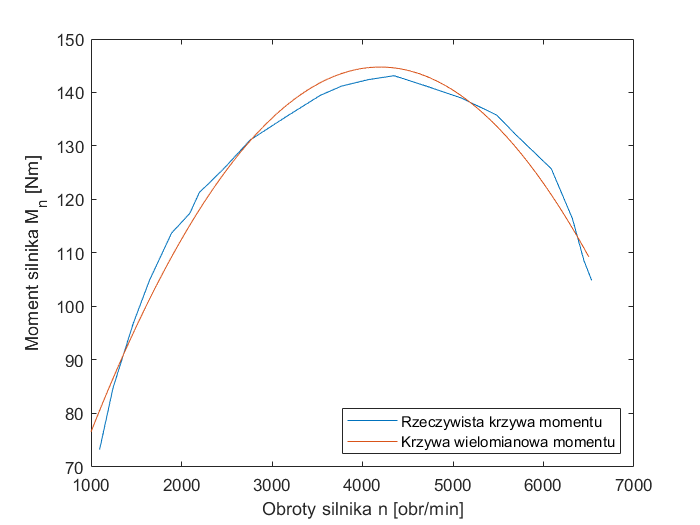

% torque curve

figure()
plot(csv_data(:,1), csv_data(:,2), 'DisplayName', "Rzeczywista krzywa momentu")
hold on

xi = 1000:6500;
plot(xi, polyval(torque_curve_f, xi), "DisplayName", "Krzywa wielomianowa momentu")
hold off

ylabel("Moment silnika M_n [Nm]")
xlabel("Obroty silnika n [obr/min]")

legend('Location', "southeast")
saveas(gcf, "./img/trq_curve.png")

% run simulation
run("car_model")

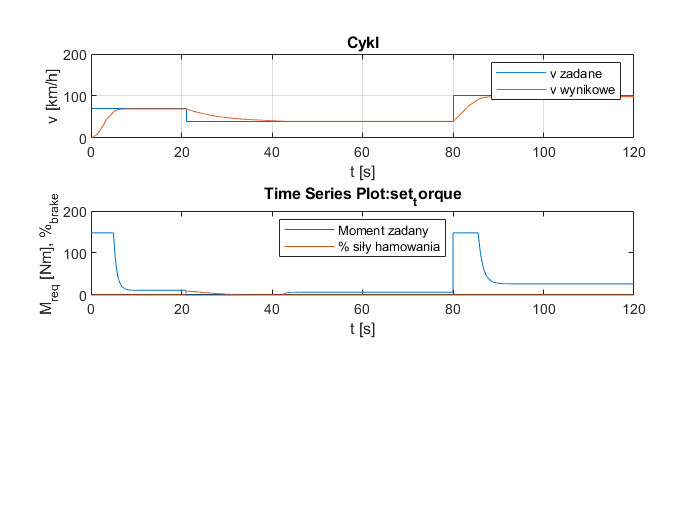

% plot drive

figure()
subplot(311)

plot(car1.speed_cycle, "DisplayName", "v zadane")
hold on
plot(car1.v*3.6, "DisplayName", "v wynikowe")
hold off

ylim([0 200])
grid()
ylabel("v [km/h]")
xlabel("t [s]")
title("Cykl")
legend()

% torque & brake plot
subplot(312)
plot(car1.set_torque, 'DisplayName', 'Moment zadany')
hold on
plot(car1.set_brake, 'DisplayName', '% siły hamowania')
hold off

ylim([0 200])
xlabel("t [s]")
ylabel("M_{req} [Nm], %_{brake}")

legend('Location',"north")


%speed plot

